# AFBM

## Load data set

Directory of PointClouds and Fold files

clc
clear
user_name = "Zachariah";
% Location of Point Clouds
datapath = strcat("C:\Users\", user_name, "\OneDrive - Oregon State University\Research\AFBM\AFBM Code\AllClouds10k\AllClouds10k\");
% Location of fold CSV files
foldpath = strcat("C:\Users\", user_name, "\Box\Automated Functional Basis Modeling\ShapeNetCore.v2\20k_10folds_multilabel_nochairs\");

Load ShapeNet Clouds

foldsTrain = 1:7;
foldsVal = 8:10;
[dsTrain, tfunc] = loadShapeNetData(foldpath, foldsTrain, datapath);
[dsVal, vfunc] = loadShapeNetData(foldpath, foldsVal, datapath);

global funcid
funcid = vertcat(tfunc(1:7,:),vfunc(8:10,:));
funcid = vertcat(funcid{:}); 
lenfu = length(funcid);
funcid = reshape(funcid, [lenfu/8,8]);
mask = cellfun(@(x) any(isa(x,'missing')), funcid);
funcid(mask) = {''}; % {'na'} 

Read one of the training samples and visualize it using `pcshow`.

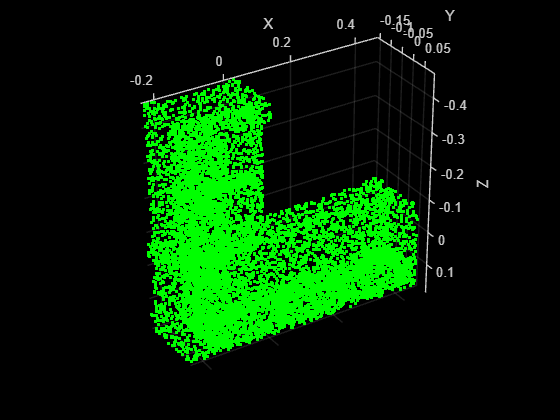

data = read(dsTrain); % funcid
ptCloud = data{1,1};
label = data{1,2};

figure
pcshow(ptCloud.Location,[0 1 0],"MarkerSize",40,"VerticalAxisDir","down")
xlabel("X")
ylabel("Y")
zlabel("Z")
title(label)

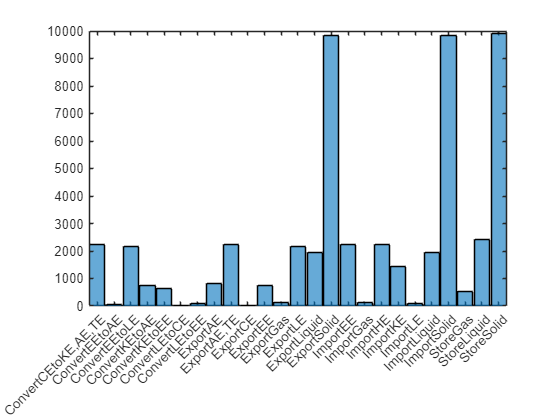

labels = funcid(:,3:8);
figure
histogram(categorical(labels))

labelsvert = vertcat(labels(:,1),labels(:,2),labels(:,3),labels(:,4),labels(:,5),labels(:,6));
labelsvert = labelsvert(~cellfun('isempty',labelsvert));
global uniquelabels
uniquelabels = unique(labelsvert);
numLabels = length(uniquelabels);

Data Augmentation (add noise, randomly rotate pointcloud)

dsTrain = transform(dsTrain,@augmentPointCloud);
numPoints = 5000;
dsTrain = transform(dsTrain,@(data)selectPoints(data,numPoints));
dsVal = transform(dsVal,@(data)selectPoints(data,numPoints));

Point Cloud Size Normalization

dsTrain = transform(dsTrain,@preprocessPointCloud);
dsVal = transform(dsVal,@preprocessPointCloud);

Preview the augmented and preprocessed training data. 

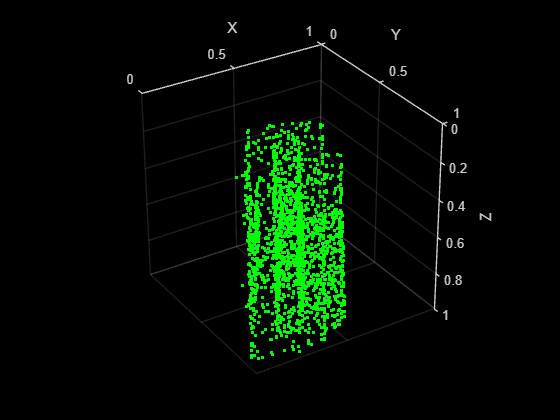

data = preview(dsTrain);
figure
pcshow(data{1,1},[0 1 0],"MarkerSize",40,"VerticalAxisDir","down");
xlabel("X")
ylabel("Y")
zlabel("Z")
title(data{1,2})

## MLC-PointNet Model

### Define PointNet Encoder Model Parameters

inputChannelSize = 3;
hiddenChannelSize1 = [64,128];
hiddenChannelSize2 = 256;
[parameters.InputTransform, state.InputTransform] = initializeTransform(inputChannelSize,hiddenChannelSize1,hiddenChannelSize2);
inputChannelSize = 3;
hiddenChannelSize = [64 64];
[parameters.SharedMLP1,state.SharedMLP1] = initializeSharedMLP(inputChannelSize,hiddenChannelSize);
inputChannelSize = 64;
hiddenChannelSize1 = [64,128];
hiddenChannelSize2 = 256;
[parameters.FeatureTransform, state.FeatureTransform] = initializeTransform(inputChannelSize,hiddenChannelSize,hiddenChannelSize2);
inputChannelSize = 64;
hiddenChannelSize = 64;
[parameters.SharedMLP2,state.SharedMLP2] = initializeSharedMLP(inputChannelSize,hiddenChannelSize);

###  Define PointNet Classifier Model Parameters

The PointNet classifier model consists of a shared MLP, a fully connected operation, and a softmax activation. For AFBM multi-label classification, we changed the softmax to a sigmoid activation. 

inputChannelSize = 64;
hiddenChannelSize = [512,256];
numClasses = numLabels; 
[parameters.ClassificationMLP, state.ClassificationMLP] = initializeClassificationMLP(inputChannelSize,hiddenChannelSize,numClasses);

## Specify Training Options

Train for 10 epochs and load data in batches of 128. Set the initial learning rate to 0.003 and the L2 regularization factor to 0.01. 

numEpochs = 10;
learnRate = 0.003; 
miniBatchSize = 128;
l2Regularization = 0.01; 
learnRateDropPeriod = 15;
learnRateDropFactor = 0.5;
thresholdvalue = 0.5;

Initialize the options for Adam optimization. 

gradientDecayFactor = 0.9;
squaredGradientDecayFactor = 0.999;

## Train MLC-PointNet

avgGradients = [];
avgSquaredGradients = [];

Train the model if `doTraining` is true. 

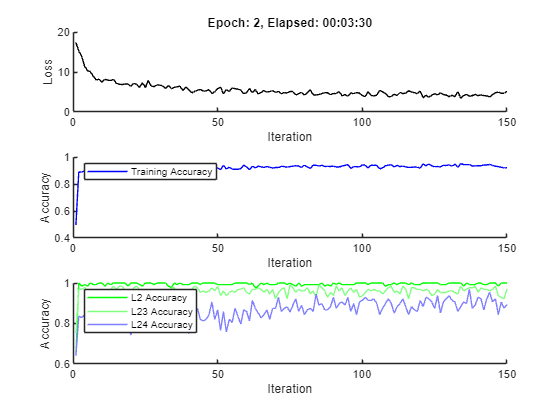

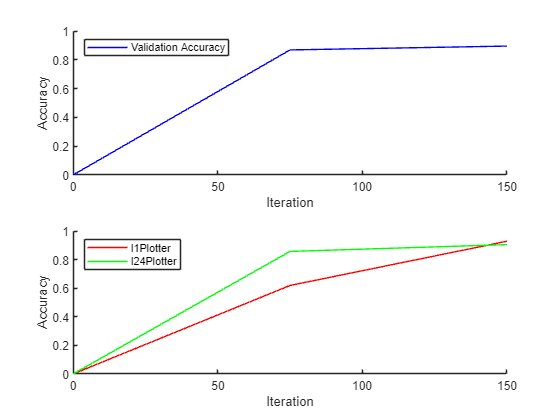

doTraining = true;

if doTraining
    
    % Create a minibatchqueue to batch data from training and validation datastores.
    numOutputsFromDSRead = 2;
    mbqTrain = minibatchqueue(dsTrain,numOutputsFromDSRead,...
        "MiniBatchSize", miniBatchSize,...
        "MiniBatchFcn",@batchData,...
        "MiniBatchFormat",["SCSB" "BC"]);

    mbqVal = minibatchqueue(dsVal,numOutputsFromDSRead,...
    "MiniBatchSize", miniBatchSize,... 
    "MiniBatchFcn",@batchData,...
    "MiniBatchFormat",["SCSB" "BC"]); 

    % Training Plot
    [lossPlotter, trainAccPlotter,l2tPlotter,l23tPlotter,l24tPlotter] = initializeTrainingProgressPlot;
    [valAccPlotter,l1vPlotter,l24vPlotter] = initializeValidationProgressPlot;
    meanacc = 0;
    iteration = 0;
    addpoints(valAccPlotter,iteration,meanacc);
    addpoints(l1vPlotter,iteration,0);
    addpoints(l24vPlotter,iteration,0);
    ValAcc = [];
    iteration = 0;
    start = tic;
 
    for epoch = 1:numEpochs
        
        % Shuffle data every epoch.
        shuffle(mbqTrain);
        
        % Iterate through data set.
        while hasdata(mbqTrain)
            iteration = iteration + 1;
            
            % Read next batch of training data.
            [XTrain, YTrain] = next(mbqTrain);            
            
            % Evaluate the model gradients and loss using dlfeval and the
            % modelGradients function.
            [gradients, loss, state, tlacc, taggacc] = dlfeval(@modelGradients,XTrain,YTrain,parameters,state);
            
            % L2 regularization.
            gradients = dlupdate(@(g,p) g + l2Regularization*p,gradients,parameters);
            
            % Update the network parameters using the Adam optimizer.
            [parameters, avgGradients, avgSquaredGradients] = adamupdate(parameters, gradients, ...
                avgGradients, avgSquaredGradients, iteration,...
                learnRate,gradientDecayFactor, squaredGradientDecayFactor);
            
            % Update the training progress.
            D = duration(0,0,toc(start),"Format","hh:mm:ss");
            title(lossPlotter.Parent,"Epoch: " + epoch + ", Elapsed: " + string(D))
            addpoints(lossPlotter,iteration,double(gather(extractdata(loss))))
            addpoints(trainAccPlotter,iteration,taggacc);
            addpoints(l2tPlotter,iteration,tlacc(2));
            addpoints(l23tPlotter,iteration,tlacc(23));
            addpoints(l24tPlotter,iteration,tlacc(24));
            drawnow
        end

       
        cmatbase = sparse(2,2);
        matts = {};
        for i=1:length(uniquelabels)
            matts{i} = cmatbase;
        end
        
        while hasdata(mbqVal)
            % Read next batch of validation data.
            [XVal, YVal] = next(mbqVal);
        
            % Compute label predictions.
            isTraining = false;
            YPred = pointnetClassifier(XVal,parameters,state,isTraining);
            
            YValAr = gather(extractdata(YVal));
            YPredAr = gather(extractdata(YPred));
            YPredAr(YPredAr < thresholdvalue) = 0;
            YPredAr(YPredAr ~= 0) = 1;
            for i=1:length(uniquelabels)
                [m,n] = size(cmatbase);
                ys = YPredAr(i,:);
                ys(2,:) = YValAr(i,:);
                ys = transpose(ys);
                fn = length(find(ys(:,1) == 0 & ys(:,2) == 1));
                fp = length(find(ys(:,1) == 1 & ys(:,2) == 0));
                tn = length(find(ys(:,1) == 0 & ys(:,2) == 0));
                tp = length(find(ys(:,1) == 1 & ys(:,2) == 1));
                cm = [tp fn;
                      fp tn];
                vlacc(i) = sum(diag(cm) / sum(cm,"all"));
                matts{i} = matts{i} + cm;
            end
        end
        % Update training progress plot with average classification accuracy.
        meanacc = mean(vlacc);
        addpoints(valAccPlotter,iteration,meanacc);
        addpoints(l1vPlotter,iteration,vlacc(1));
        addpoints(l24vPlotter,iteration,vlacc(24));

        % Update the learning rate.
        if mod(epoch,learnRateDropPeriod) == 0
            learnRate = learnRate * learnRateDropFactor;
        end
        
        % Reset training and validation data queues.
        reset(mbqTrain);
        reset(mbqVal);
    end

end

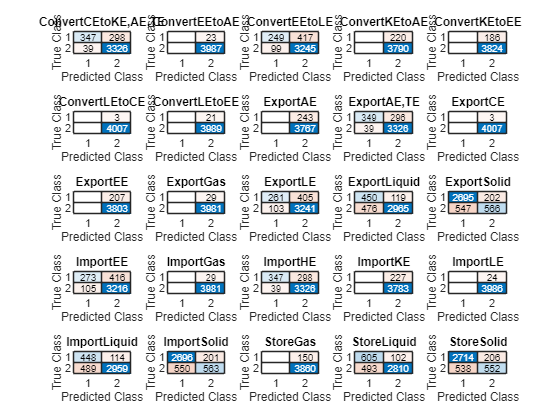

figure
tiledlayout("flow")
evalmet = {'Label' 'Accuracy' 'Precision' 'Recall' 'F1 Score'};
for i=1:length(uniquelabels)
    cm = matts{i};
    lacc(i) = sum(diag(cm)) / sum(cm,"all");
    precision(i) = cm(1) / (cm(1) + cm(3));
    recall(i) = cm(1) / (cm(1) + cm(2));
    f1(i) = (2*cm(1)) / ((2*cm(1)) + cm(2) + cm(3));
    evalmet{i+1,1} = uniquelabels(i); evalmet{i+1,2} = lacc(i); evalmet{i+1,3} = precision(i);evalmet{i+1,4} = recall(i);evalmet{i+1,5} = f1(i);
    nexttile
    confusionchart(cm)
    title(uniquelabels(i))
end

disp(evalmet)

    {'Label' }    {'Accuracy'}    {'Precision'}    {'Recall'}    {'F1 Score'}
    {1×1 cell}    {[  0.9160]}    {[   0.5380]}    {[0.8990]}    {[  0.6731]}
    {1×1 cell}    {[  0.9943]}    {[        0]}    {[   NaN]}    {[       0]}
    {1×1 cell}    {[  0.8713]}    {[   0.3739]}    {[0.7155]}    {[  0.4911]}
    {1×1 cell}    {[  0.9451]}    {[        0]}    {[   NaN]}    {[       0]}
    {1×1 cell}    {[  0.9536]}    {[        0]}    {[   NaN]}    {[       0]}
    {1×1 cell}    {[  0.9993]}    {[        0]}    {[   NaN]}    {[       0]}
    {1×1 cell}    {[  0.9948]}    {[        0]}    {[   NaN]}    {[       0]}
    {1×1 cell}    {[  0.9394]}    {[        0]}    {[   NaN]}    {[       0]}
    {1×1 cell}    {[  0.9165]}    {[   0.5411]}    {[0.8995]}    {[  0.6757]}
    {1×1 cell}    {[  0.9993]}    {[        0]}    {[   NaN]}    {[       0]}
    {1×1 cell}    {[  0.9484]}    {[        0]}    {[   NaN]}    {[       0]}
    {1×1 cell}    {[  0.9928]}    {[        0]}    {[   NaN]}   

evalmet_tab = cell2table(evalmet);
writetable(evalmet_tab,'evalmet_10epoch_14kclouds_10kpoints3.csv')
matts_tab = cell2table(matts);
writetable(matts_tab,'matts10e14kc10kp3.csv')

## Validate Network 

numOutputsFromDSRead = 2;
miniBatchSize = 128;
mbqVal = minibatchqueue(dsVal,numOutputsFromDSRead,...
    "MiniBatchSize", miniBatchSize,... 
    "MiniBatchFcn",@batchData,...
    "MiniBatchFormat",["SCSB" "BC"]);

cmatbase = sparse(2,2);
matts = {};
threshmatts = {};
thresheval = {};
for i=1:length(uniquelabels)
    matts{i} = cmatbase;
end
%batch = 1;
evalmet = {'Label' 'Threshold' 'Accuracy' 'Precision' 'Recall' 'F1 Score'};
thresh = 0.1:0.1:1;
for t=1:length(thresh)
    for i=1:length(uniquelabels)
        matts{i} = cmatbase;
    end
    while hasdata(mbqVal)
        % Read next batch of validation data.
        [XVal, YVal] = next(mbqVal);
        % Compute label predictions.
        isTraining = false;
        YPred = pointnetClassifier(XVal,parameters,state,isTraining);
        YValAr = gather(extractdata(YVal));
        YPredAr = gather(extractdata(YPred));
        YPredAr(YPredAr < thresh(t)) = 0;
        YPredAr(YPredAr ~= 0) = 1;
        for i=1:length(uniquelabels)
            [m,n] = size(cmatbase);
            ys = YPredAr(i,:);
            ys(2,:) = YValAr(i,:);
            ys = transpose(ys);
            fn = length(find(ys(:,1) == 0 & ys(:,2) == 1));
            fp = length(find(ys(:,1) == 1 & ys(:,2) == 0));
            tn = length(find(ys(:,1) == 0 & ys(:,2) == 0));
            tp = length(find(ys(:,1) == 1 & ys(:,2) == 1));
            cm = [tp fn;
                  fp tn];
            matts{i} = matts{i} + cm;
        end
    end
    for i=1:length(uniquelabels)
        cm = matts{i};
        evalmet{i+1,1} = uniquelabels(i); 
        evalmet{i+1,2} = thresh(t);
        evalmet{i+1,3} = sum(diag(cm)) / sum(cm, "all"); 
        evalmet{i+1,4} = cm(1) / (cm(1) + cm(3));
        evalmet{i+1,5} = cm(1) / (cm(1) + cm(2)); 
        evalmet{i+1,6} = (2*cm(1)) / (2*cm(1) + cm(2) + cm(3)); 
    end
    evalmet_tab = cell2table(evalmet);
    filestr = 'evalmet_10epoch_14kclouds_10kpointsRun3_thresh' + string(thresh(t)) + '.csv';
    writetable(evalmet_tab,filestr)
    matts_tab = cell2table(matts);
    filestr = 'confusionmatrix_10epoch_14kclouds_10kpointsRun3_thresh' + string(thresh(t)) + '.csv';
    writetable(matts_tab,filestr)
    reset(mbqVal)
end

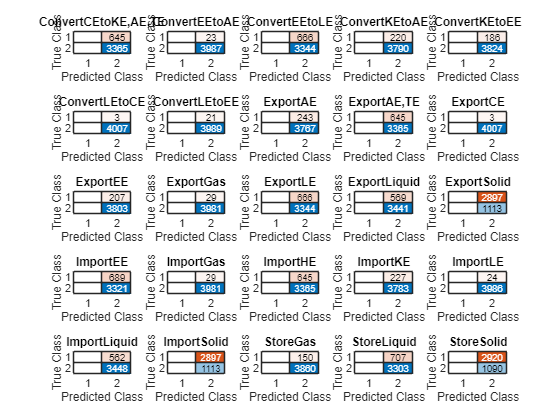

figure
tiledlayout("flow")
evalmet = {'Label' 'Accuracy' 'Precision' 'Recall' 'F1 Score'};
for i=1:length(uniquelabels)
    cm = matts{i};
    lacc(i) = sum(diag(cm) / sum(cm,"all"));
    precision(i) = cm(1) / (cm(1) + cm(3));
    recall(i) = cm(1) / (cm(1) + cm(2));
    f1(i) = (2*cm(1) / ((2*cm(1))) + cm(2) + cm(3));
    evalmet{i+1,1} = uniquelabels(i); evalmet{i+1,2} = lacc(i); evalmet{i+1,3} = precision(i);evalmet{i+1,4} = recall(i);evalmet{i+1,5} = f1(i);
    nexttile
    confusionchart(cm)
    title(uniquelabels(i))
end

disp(evalmet)

    {'Label' }    {'Accuracy'}    {'Precision'}    {'Recall'}    {'F1 Score'}
    {1×1 cell}    {[  0.8392]}    {[        0]}    {[   NaN]}    {[     NaN]}
    {1×1 cell}    {[  0.9943]}    {[        0]}    {[   NaN]}    {[     NaN]}
    {1×1 cell}    {[  0.8339]}    {[        0]}    {[   NaN]}    {[     NaN]}
    {1×1 cell}    {[  0.9451]}    {[        0]}    {[   NaN]}    {[     NaN]}
    {1×1 cell}    {[  0.9536]}    {[        0]}    {[   NaN]}    {[     NaN]}
    {1×1 cell}    {[  0.9993]}    {[        0]}    {[   NaN]}    {[     NaN]}
    {1×1 cell}    {[  0.9948]}    {[        0]}    {[   NaN]}    {[     NaN]}
    {1×1 cell}    {[  0.9394]}    {[        0]}    {[   NaN]}    {[     NaN]}
    {1×1 cell}    {[  0.8392]}    {[        0]}    {[   NaN]}    {[     NaN]}
    {1×1 cell}    {[  0.9993]}    {[        0]}    {[   NaN]}    {[     NaN]}
    {1×1 cell}    {[  0.9484]}    {[        0]}    {[   NaN]}    {[     NaN]}
    {1×1 cell}    {[  0.9928]}    {[        0]}    {[   NaN]}   

evalmet_tab = cell2table(evalmet);
writetable(evalmet_tab,'evalmet_5epoch_60kclouds_10kpoints10.csv')
matts_tab = cell2table(matts);
writetable(matts_tab,'matts5e60kc10kp10.csv')

% Do the precision, recall, accuracy, f1 after everything. Go through the
% "Matts" cell and calculate those quantities
fid = fopen('thresheval5.json','w');
jthresheval = jsonencode(thresheval);
fprintf(fid,'%s',jthresheval);
fclose(fid);

fid = fopen('thresmatts5.json','w');
jthreshmatts = jsonencode(threshmatts);
fprintf(fid,'%s',jthreshmatts);
fclose(fid);

## Classify Point Cloud Data Using PointNet

Load point cloud data with `pcread`, preprocess the point cloud using the same function used during training, and convert the result to a `dlarray`.  

file = "C:\Users\Zachariah\OneDrive - Oregon State University\Research\AFBM\AFBM Code\AllClouds10k\AllClouds10k\lamp_3636649_3edde0735bdd2aeec8bd09a8ecef3d421_10000_2pc.ply";
ptCloud = pcread(file);
X = preprocessPointCloud(ptCloud);
dlX = dlarray(X{1},"SCSB");
YPred = pointnetClassifier(dlX,parameters,state,false);
YPredd = gather(extractdata(YPred));
YCell = num2cell(YPredd);
YCell(:,2) = cellstr(string(uniquelabels(1:25)));

mask = cellfun(@(x) x < 0.5, YCell(:,1));
mask(:,2) = mask;
YCell(mask) = [];
lenYCell = length(YCell);
YCell = reshape(YCell, [lenYCell/2,2]);
disp(YCell)

    {[0.5719]}    {'ConvertEEtoLE'}
    {[0.5847]}    {'ExportLE'     }
    {[0.5991]}    {'ImportEE'     }



Display the point cloud and the predicted label with the highest score. 

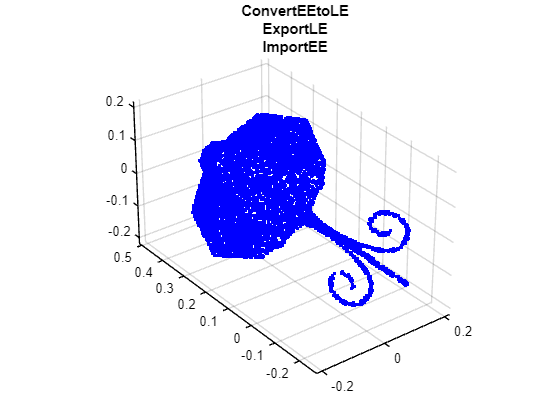

figure
pcshow(ptCloud.Location,[0 0 1],"MarkerSize",40,"VerticalAxisDir","up","BackgroundColor",'w')
title(YCell(:,2))

ptCloud = pcread("C:\Users\Zachariah\Box\Automated Functional Basis Modeling\ShapeNetCore.v2\AllClouds10k\guitar_3467517_22b29fbbf99e9cbde1c6f6ff6004a0511_10000_2pc.ply");
X = preprocessPointCloud(ptCloud);
dlX = dlarray(X{1},"SCSB");
YPred = pointnetClassifier(dlX,parameters,state,false);
YPredd = gather(extractdata(YPred));
YCell = num2cell(YPredd);
YCell(:,2) = cellstr(string(uniquelabels));

mask = cellfun(@(x) x < 0.5, YCell(:,1));
mask(:,2) = mask;
YCell(mask) = [];
lenYCell = length(YCell);
YCell = reshape(YCell, [lenYCell/2,2]);
disp(YCell)

    {[0.9554]}    {'ExportSolid'}
    {[0.9556]}    {'ImportSolid'}
    {[0.9541]}    {'StoreSolid' }



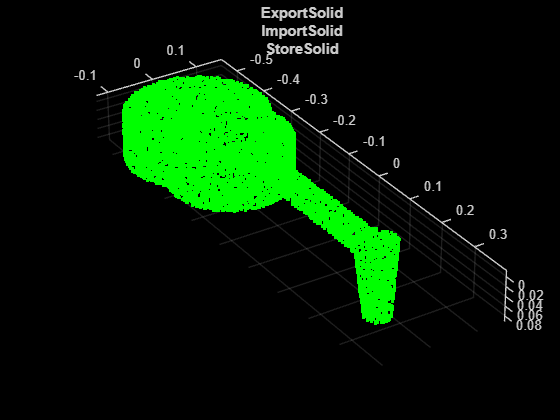

figure
pcshow(ptCloud.Location,[0 1 0],"MarkerSize",40,"VerticalAxisDir","down")
title(YCell(:,2))

## Model Gradients Function

function [gradients, loss, state, lacc, aggacc] = modelGradients(X,Y,parameters,state)
global uniquelabels

% Execute the model function.
isTraining = true;
[YPred,state,dlT] = pointnetClassifier(X,parameters,state,isTraining);

% Add regularization term to ensure feature transform matrix is
% approximately orthogonal.
K = size(dlT,1);
B = size(dlT, 4);
I = repelem(eye(K),1,1,1,B);
dlI = dlarray(I,"SSCB");
treg = mse(dlI,pagemtimes(dlT,permute(dlT,[2 1 3 4])));
factor = 0.001;

% Compute the loss.
loss = crossentropy(YPred,Y,'ClassificationMode','multilabel') + factor*treg; %Changed to multi label! loss = crossentropy(YPred,Y) + factor*treg;

% Compute the parameter gradients with respect to the loss. 
gradients = dlgradient(loss, parameters);

% Compute training accuracy metric.
YAr = gather(extractdata(Y));
YPredAr = gather(extractdata(YPred));
YPredAr(YPredAr < 0.5) = 0;
YPredAr(YPredAr ~= 0) = 1;
for i=1:length(uniquelabels)
    ys = YPredAr(i,:);
    ys(2,:) = YAr(i,:);
    ys = transpose(ys);
    fn = length(find(ys(:,1) == 0 & ys(:,2) == 1));
    fp = length(find(ys(:,1) == 1 & ys(:,2) == 0));
    tn = length(find(ys(:,1) == 0 & ys(:,2) == 0));
    tp = length(find(ys(:,1) == 1 & ys(:,2) == 1));
    cm = [tp fn;
          fp tn];
    lacc(i) = sum(diag(cm) / sum(cm,"all"));
end
aggacc = mean(lacc);

end

## PointNet Classifier Function

function [dlY,state,dlT] = pointnetClassifier(dlX,parameters,state,isTraining)

% Invoke the PointNet encoder.
[dlY,state,dlT] = pointnetEncoder(dlX,parameters,state,isTraining);

% Invoke the classifier.
p = parameters.ClassificationMLP.Perceptron;
s = state.ClassificationMLP.Perceptron;
for k = 1:numel(p) 
     
    [dlY, s(k)] = perceptron(dlY,p(k),s(k),isTraining);
      
    % If training, apply inverted dropout with a probability of 0.3.
    if isTraining
        probability = 0.3; 
        dropoutScaleFactor = 1 - probability;
        dropoutMask = ( rand(size(dlY), "like", dlY) > probability ) / dropoutScaleFactor;
        dlY = dlY.*dropoutMask;
    end
    
end
state.ClassificationMLP.Perceptron = s;

% Apply final fully connected and softmax operations.
weights = parameters.ClassificationMLP.FC.Weights;
bias = parameters.ClassificationMLP.FC.Bias;
dlY = fullyconnect(dlY,weights,bias);
dlY = sigmoid(dlY); %UPDATED TO SIGMOID FOR MULTI-LABEL FROM SOFTMAX softmax(dlY);
end

## PointNet Encoder Function

function [dlY,state,T] = pointnetEncoder(dlX,parameters,state,isTraining)
% Input transform.
[dlY,state.InputTransform] = dataTransform(dlX,parameters.InputTransform,state.InputTransform,isTraining);

% Shared MLP.
[dlY,state.SharedMLP1.Perceptron] = sharedMLP(dlY,parameters.SharedMLP1.Perceptron,state.SharedMLP1.Perceptron,isTraining);

% Feature transform.
[dlY,state.FeatureTransform,T] = dataTransform(dlY,parameters.FeatureTransform,state.FeatureTransform,isTraining);

% Shared MLP.
[dlY,state.SharedMLP2.Perceptron] = sharedMLP(dlY,parameters.SharedMLP2.Perceptron,state.SharedMLP2.Perceptron,isTraining);

% Max operation.
dlY = max(dlY,[],1);
end

## Shared Multilayer Perceptron Function

function [dlY,state] = sharedMLP(dlX,parameters,state,isTraining)
dlY = dlX;
for k = 1:numel(parameters) 
    [dlY, state(k)] = perceptron(dlY,parameters(k),state(k),isTraining);
end
end

## Perceptron Function

function [dlY,state] = perceptron(dlX,parameters,state,isTraining)
% Convolution.
W = parameters.Conv.Weights;
B = parameters.Conv.Bias;
dlY = dlconv(dlX,W,B);

% Batch normalization. Update batch normalization state when training.
offset = parameters.BatchNorm.Offset;
scale = parameters.BatchNorm.Scale;
trainedMean = state.BatchNorm.TrainedMean;
trainedVariance = state.BatchNorm.TrainedVariance;
if isTraining
    [dlY,trainedMean,trainedVariance] = batchnorm(dlY,offset,scale,trainedMean,trainedVariance);
    
    % Update state.
    state.BatchNorm.TrainedMean = trainedMean;
    state.BatchNorm.TrainedVariance = trainedVariance;
else
    dlY = batchnorm(dlY,offset,scale,trainedMean,trainedVariance);
end

% ReLU.
dlY = relu(dlY);
end

## Data Transform Function

function [dlY,state,T] = dataTransform(dlX,parameters,state,isTraining)

% Shared MLP.
[dlY,state.Block1.Perceptron] = sharedMLP(dlX,parameters.Block1.Perceptron,state.Block1.Perceptron,isTraining);

% Max operation.
dlY = max(dlY,[],1);

% Shared MLP.
[dlY,state.Block2.Perceptron] = sharedMLP(dlY,parameters.Block2.Perceptron,state.Block2.Perceptron,isTraining);

% Transform net (T-Net). Apply last fully connected operation as W*X to
% predict tranformation matrix T.
dlY = squeeze(dlY); % N-by-B
T = parameters.Transform * stripdims(dlY); % K^2-by-B

% Reshape T into a square matrix.
K = sqrt(size(T,1));
T = reshape(T,K,K,1,[]); % [K K 1 B]
T = T + eye(K);

% Apply to input dlX using batch matrix multiply. 
[C,B] = size(dlX,[3 4]);  % [M 1 K B]
dlX = reshape(dlX,[],C,1,B); % [M K 1 B]
Y = pagemtimes(dlX,T);
dlY = dlarray(Y,"SCSB");
end

## Model Parameter Initialization Functions

### `initializeTransform` Function

function [params,state] = initializeTransform(inputChannelSize,block1,block2)
[params.Block1,state.Block1] = initializeSharedMLP(inputChannelSize,block1);
[params.Block2,state.Block2] = initializeSharedMLP(block1(end),block2);

% Parameters for the transform matrix.
params.Transform = dlarray(zeros(inputChannelSize^2,block2(end)));
end

### `initializeSharedMLP` Function

function [params,state] = initializeSharedMLP(inputChannelSize,hiddenChannelSize)
weights = initializeWeightsHe([1 1 inputChannelSize hiddenChannelSize(1)]);
bias = zeros(hiddenChannelSize(1),1,"single");
p.Conv.Weights = dlarray(weights);
p.Conv.Bias = dlarray(bias);

p.BatchNorm.Offset = dlarray(zeros(hiddenChannelSize(1),1,"single"));
p.BatchNorm.Scale = dlarray(ones(hiddenChannelSize(1),1,"single"));

s.BatchNorm.TrainedMean = zeros(hiddenChannelSize(1),1,"single");
s.BatchNorm.TrainedVariance = ones(hiddenChannelSize(1),1,"single");

params.Perceptron(1) = p;
state.Perceptron(1) = s;

for k = 2:numel(hiddenChannelSize)
    weights = initializeWeightsHe([1 1 hiddenChannelSize(k-1) hiddenChannelSize(k)]);
    bias = zeros(hiddenChannelSize(k),1,"single");
    p.Conv.Weights = dlarray(weights);
    p.Conv.Bias = dlarray(bias);
    
    p.BatchNorm.Offset = dlarray(zeros(hiddenChannelSize(k),1,"single"));
    p.BatchNorm.Scale = dlarray(ones(hiddenChannelSize(k),1,"single"));
    
    s.BatchNorm.TrainedMean = zeros(hiddenChannelSize(k),1,"single");
    s.BatchNorm.TrainedVariance = ones(hiddenChannelSize(k),1,"single");

    params.Perceptron(k) = p;
    state.Perceptron(k) = s;
end
end

### `initializeClassificationMLP` Function 

function [params,state] = initializeClassificationMLP(inputChannelSize,hiddenChannelSize,numClasses)
[params,state] = initializeSharedMLP(inputChannelSize,hiddenChannelSize);

weights = initializeWeightsGaussian([numClasses hiddenChannelSize(end)]);
bias = zeros(numClasses,1,"single");
params.FC.Weights = dlarray(weights);
params.FC.Bias = dlarray(bias);
end

### `initializeWeightsHe` Function

function x = initializeWeightsHe(sz)
fanIn = prod(sz(1:3));
stddev = sqrt(2/fanIn);
x = stddev .* randn(sz);
end

###  `initializeWeightsGaussian` Function

The `initializeWeightsGaussian` function initializes parameters using Gaussian initialization with a standard deviation of 0.01.

function x = initializeWeightsGaussian(sz)
x = randn(sz,"single") .* 0.01;
end

## Data Preprocessing Functions

### `preprocessPointCloudData` Function

function data = preprocessPointCloud(data)

if ~iscell(data)
    data = {data};
end

numObservations = size(data,1);
for i = 1:numObservations
    % Scale points between 0 and 1.
    xlim = data{i,1}.XLimits;
    ylim = data{i,1}.YLimits;
    zlim = data{i,1}.ZLimits;
    
    xyzMin = [xlim(1) ylim(1) zlim(1)];
    xyzDiff = [diff(xlim) diff(ylim) diff(zlim)];
    
    data{i,1} = (data{i,1}.Location - xyzMin) ./ xyzDiff;
end
end

### `selectPoints` Function

function data = selectPoints(data,numPoints) 
% Select the desired number of points by downsampling or replicating
% point cloud data.
numObservations = size(data,1);
for i = 1:numObservations    
    ptCloud = data{i,1};
    if ptCloud.Count > numPoints
        percentage = numPoints/ptCloud.Count;
        data{i,1} = pcdownsample(ptCloud,"random",percentage);   
    else    
        replicationFactor = ceil(numPoints/ptCloud.Count);
        ind = repmat(1:ptCloud.Count,1,replicationFactor);
        data{i,1} = select(ptCloud,ind(1:numPoints));
    end 
end
end

## Data Augmentation Functions

function data = augmentPointCloud(data)
   
numObservations = size(data,1);
for i = 1:numObservations
    
    ptCloud = data{i,1};
    
    % Rotate the point cloud about "up axis", which is Z for this data set.
    tform = randomAffine3d(...
        "XReflection", true,...
        "YReflection", true,...
        "Rotation",@randomRotationAboutZ);
    
    ptCloud = pctransform(ptCloud,tform);
    
    % Randomly drop out 30% of the points.
    if rand > 0.5
        ptCloud = pcdownsample(ptCloud,'random',0.2);
    end
    
    if rand > 0.5
        % Jitter the point locations with Gaussian noise with a mean of 0 and 
        % a standard deviation of 0.02 by creating a random displacement field.
        D = 0.02 * randn(size(ptCloud.Location));
        ptCloud = pctransform(ptCloud,D);   
    end
    
    data{i,1} = ptCloud;
end
end

function [rotationAxis,theta] = randomRotationAboutZ()
rotationAxis = [0 0 1];
theta = 360*rand;
end

## Supporting Functions

### `initializeTrainingProgressPlot` Function

function [plotter,trainAccPlotter, l2Plotter,l23Plotter,l24Plotter] = initializeTrainingProgressPlot()
% Plot the loss, training accuracy, and validation accuracy.
figure

% Loss plot
subplot(3,1,1)
plotter = animatedline;
xlabel("Iteration")
ylabel("Loss")

% Accuracy plot
subplot(3,1,2)
trainAccPlotter = animatedline('Color','b');
legend('Training Accuracy','Location','northwest');
xlabel("Iteration")
ylabel("Accuracy")

% Label Accuracy plot
subplot(3,1,3)
l2Plotter = animatedline("Color","#00FF00");
l23Plotter = animatedline("Color",[0.5 1 0.5]);
l24Plotter = animatedline("Color",[0.5 0.5 1]);
legend('L2 Accuracy','L23 Accuracy','L24 Accuracy','Location','northwest');
xlabel("Iteration")
ylabel("Accuracy")
end

### `initializeValidationPlot` Function

function [valAccPlotter,l1Plotter,l2Plotter,l3Plotter,l4Plotter,l5Plotter,l6Plotter,l7Plotter,l8Plotter,l9Plotter,l10Plotter,...
        l11Plotter,l12Plotter,l13Plotter,l14Plotter,l15Plotter,l16Plotter,l17Plotter,l18Plotter,l19Plotter,l20Plotter,l21Plotter,l22Plotter,l23Plotter,...
        l24Plotter,l25Plotter] = initializeValidationProgressPlot()
% Plot the loss, training accuracy, and validation accuracy.
figure
% Accuracy plot
subplot(2,1,1)
valAccPlotter = animatedline('Color','b');
legend('Validation Accuracy', 'Location','northwest');
xlabel("Iteration")
ylabel("Accuracy")

% Label Accuracy
subplot(2,1,2)
l1Plotter = animatedline("Color","#FF0000");
l2Plotter = animatedline("Color","#00FF00");
l3Plotter = animatedline("Color","#0000FF");
l4Plotter = animatedline("Color","#00FFFF");
l5Plotter = animatedline("Color","#FF00FF");
l6Plotter = animatedline("Color","#FFFF00");
l7Plotter = animatedline("Color","#000000");
l8Plotter = animatedline("Color","#0072BD");
l9Plotter = animatedline("Color","#D95319");
l10Plotter = animatedline("Color","#EDB120");
l11Plotter = animatedline("Color","#7E2F8E");
l12Plotter = animatedline("Color","#77AC30");
l13Plotter = animatedline("Color","#4DBEEE");
l14Plotter = animatedline("Color","#A2142F");
l15Plotter = animatedline("Color",[0 0.60 0.7]);
l16Plotter = animatedline("Color",[0.2 0.8 0.7410]);
l17Plotter = animatedline("Color",[0.9 0.4470 0.7410]);
l18Plotter = animatedline("Color",[1 0.4470 0.7410]);
l19Plotter = animatedline("Color",[1 0.7 0.7]);
l20Plotter = animatedline("Color",[0.7 0.7 1]);
l21Plotter = animatedline("Color",[0.7 1 0.7]);
l22Plotter = animatedline("Color",[0.5 0.5 1]);
l23Plotter = animatedline("Color",[0.5 1 0.5]);
l24Plotter = animatedline("Color",[0.5 0.5 1]);
l25Plotter = animatedline("Color",[0.5 1 0]);
%legend('l1Plotter','l2Plotter','l3Plotter','l4Plotter','l5Plotter','l6Plotter','l7Plotter','l8Plotter','l9Plotter','l10Plotter',...
%       'l11Plotter','l12Plotter','l13Plotter','l14Plotter','l15Plotter','l16Plotter','l17Plotter','l18Plotter','l19Plotter','l20Plotter',...
%        'l21Plotter','l22Plotter','l23Plotter','l24Plotter','l25Plotter', 'Location','northwest');
legend('l1Plotter','l24Plotter','Location','northwest');
xlabel("Iteration")
ylabel("Accuracy")
end

### `loadShapeNetData` Function

function [ds,func] = loadShapeNetData(foldpath, folds, datapath)

if nargin == 0
    return;
end

if nargin < 2
    folds = 1:10;
end

foldpath = string(foldpath);
vars = [];
%needs to be updated
for i=folds(1):folds(end)
    fstr = 'fold_' + string(i-1);
    fold = readcell(fullfile(foldpath, fstr));
    func{i,1} = fold(2:end,6);
    func{i,2} = fold(2:end,3);
    func{i,3} = fold(2:end,9);
    func{i,4} = fold(2:end,10);
    func{i,5} = fold(2:end,11);
    func{i,6} = fold(2:end,12);
    func{i,7} = fold(2:end,13);
    func{i,8} = fold(2:end,14);
    foldNames{i}=fold(2:end,7);
end

for i=folds(1):folds(end)
    for j = 1:length(foldNames{i})
        temp_name = strsplit(foldNames{i}{j}, '\');
        foldNames{i}{j} = char(strcat(datapath, temp_name{end}));
    end
end

names = foldNames(folds);
names = vertcat(names{:});
fullFilenames = names; 

ds = fileDatastore(fullFilenames,'ReadFcn', @extractTrainingData,'FileExtensions','.ply'); 
end

### `batchData` Function

function [X, Y] = batchData(ptCloud, labels)
global uniquelabels

X = cat(4,ptCloud{:});
%labels = vertcat(labels{:}); % %labels = cat(1,labels{:});
labels_to_cell = cell(size(labels, 1));
for i = 1:size(labels, 1)
    labels_to_cell{i,1} = cellstr(labels{i, 1});
end
labels_to_cell = vertcat(labels_to_cell{:,1});


all_labels = uniquelabels;
numLabels = length(all_labels);


encodedLabel = zeros(size(ptCloud,1),numLabels);
for i = 1:size(ptCloud,1)
    for j = 1:size(labels_to_cell,2)
        req_index = find(strcmp(string(all_labels), labels_to_cell{i,j}));
        if req_index
            if labels_to_cell{i,j} == "na"
                encodedLabel(i, req_index) = 0;
            else
                encodedLabel(i, req_index) = 1;
            end
        end
    end

end
Y = encodedLabel(:,1:25);
end

### `extractTrainingData` Function

function dataOut = extractTrainingData(fname) 
global funcid;
[pointData, Normal, Intensity] = readply(fname);
fid = strsplit(fname, 'AllClouds10k\'); 
fid = char(fid(2));
fid = strsplit(fid, '_');
categor = fid(1:end-4);
catt = string(categor(1));
for i=2:length(categor)
    catt = catt + '_' + string(categor(i));
end
fid = (fid(end-2));
[r1, ~] = find(strcmp(funcid, fid)); 
if length(r1)>1
    [r2, ~] = find(strcmp(funcid, catt)); 
    idx = [];
    i = 1;
    for i=1:length(r1)
        idx = find(r1(i)==r2);
        if ~isempty(idx)
            r = r1(i);
            break
        end
    end
else
    r = r1;
end


f1 = string(funcid{r,3});
f2 = string(funcid{r,4});
f3 = string(funcid{r,5});
f4 = string(funcid{r,6});
f5 = string(funcid{r,7});
f6 = string(funcid{r,8});
func = [f1,f2,f3,f4,f5,f6];
label = categorical(func); 

dataOut = {pointCloud(pointData,'Normal', Normal, 'Intensity', Intensity),label};
end

### `readply` Function

function [pointData, Normal, Intensity] = readply(fname)
cloud = pcread(fname);
pointData = cloud.Location();
Normal = cloud.Normal();
Intensity = cloud.Intensity();
end

### `prepareForPrediction` Function

function p = prepareForPrediction(p,fcn)

for i = 1:numel(p)
    p(i) = structfun(@(x)invoke(fcn,x),p(i),'UniformOutput',0);
end

    function data = invoke(fcn,data)
        if isstruct(data)
            data = prepareForPrediction(data,fcn);
        else
            data = fcn(data);
        end
    end
end

% Move data to the GPU.
function x = toDevice(x,useGPU)
if useGPU
    x = gpuArray(x);
end
end